Mathias Bruun Houmøller            -            202006837

# M3NUM1 F15 Reeksamen opgave 3

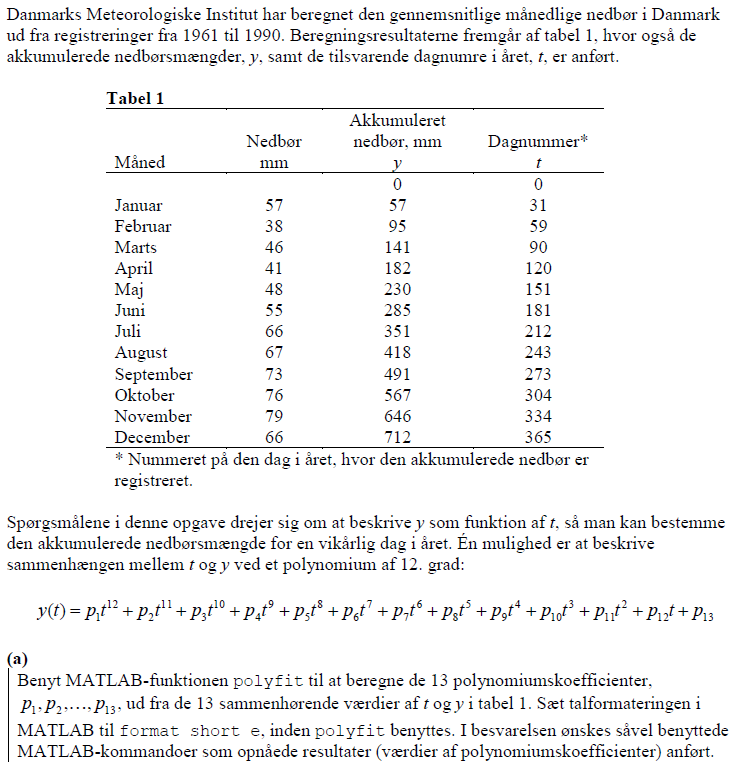

format short e %formater til 4 decimaler i e form
y = [0 57 95 141 182 230 285 351 418 491 567 646 712]'; %data inlæses
x = [0 31 59 90 120 151 181 212 243 273 204 334 365]';
P_fit = polyfit(x,y,12)'; %bruger polyfit til at lave et 12grad polynomie der går igennem alle data punkter

% her vises alle skalarene(p) i tabelen 
T = table(P_fit, x, y);
disp(T)

       P_fit           x             y     
    ___________    __________    __________

    -8.6767e-21    0.0000e+00    0.0000e+00
     1.7866e-17    3.1000e+01    5.7000e+01
    -1.6199e-14    5.9000e+01    9.5000e+01
     8.5173e-12    9.0000e+01    1.4100e+02
    -2.8774e-09    1.2000e+02    1.8200e+02
     6.5364e-07    1.5100e+02    2.3000e+02
    -1.0147e-04    1.8100e+02    2.8500e+02
     1.0710e-02    2.1200e+02    3.5100e+02
    -7.4849e-01    2.4300e+02    4.1800e+02
     3.2713e+01    2.7300e+02    4.9100e+02
    -7.9580e+02    2.0400e+02    5.6700e+02
     8.0388e+03    3.3400e+02    6.4600e+02
    -1.3481e-04    3.6500e+02    7.1200e+02



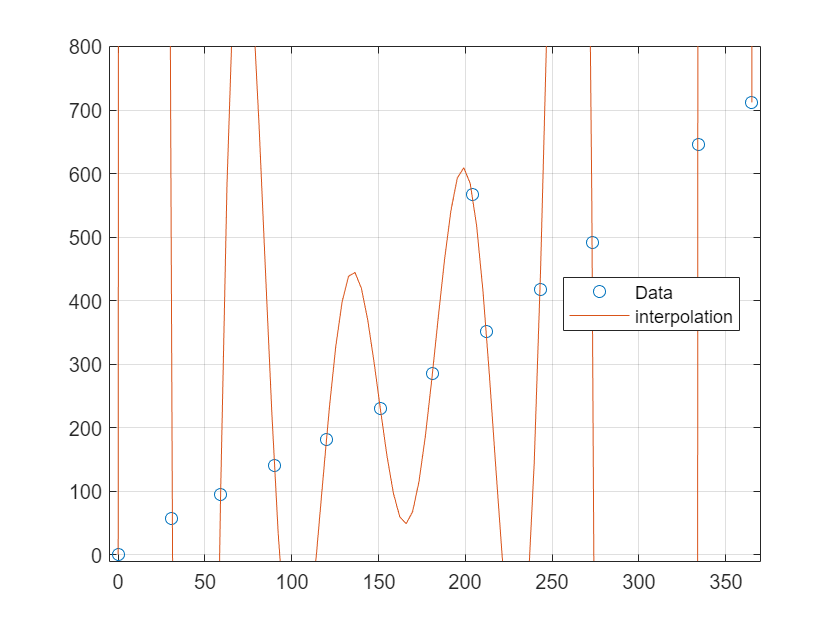

%data en plottes for at se hvordan vores fit ligger
xx = linspace(0,365); %laver 100 værdier ligeligt fordelt fra 0 til 365
yy = polyval(P_fit,xx); %giver de interpolatede y værdier fra xx værdierne
%der plottes
figure
plot(x,y,'o', 'DisplayName', 'Data')
hold on
plot(xx,yy, 'DisplayName', 'interpolation - polynmie')
legend('location', 'best')
xlim([-5, 370])
ylim([-10,800])
grid
hold off

ned_int_100 = interp1(x,y,100,"linear")

ned_int_100 =    1.5467e+02


% ned_pol_100 = intpl1(P_fit,100) % der indsættes dag 100 i polyval som retunere y(100) af 12. gradspolynomiet.

Således er vores nedbør 155 mm

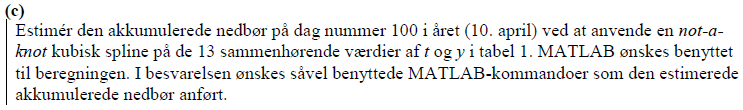

ned_spl_100 = spline(x,y,100) %spline bruges til at lave interpolation imellem værdierne.

ned_spl_100 =    1.5111e+02


% når der er gevet 2 vektor med samme lægnde benyttes not-a-knot metoden.

således fås 151 mm nedbør på dag 100

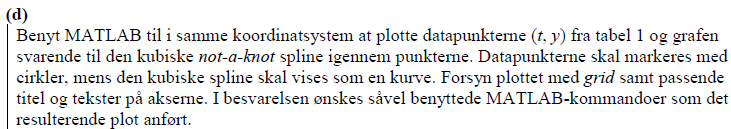

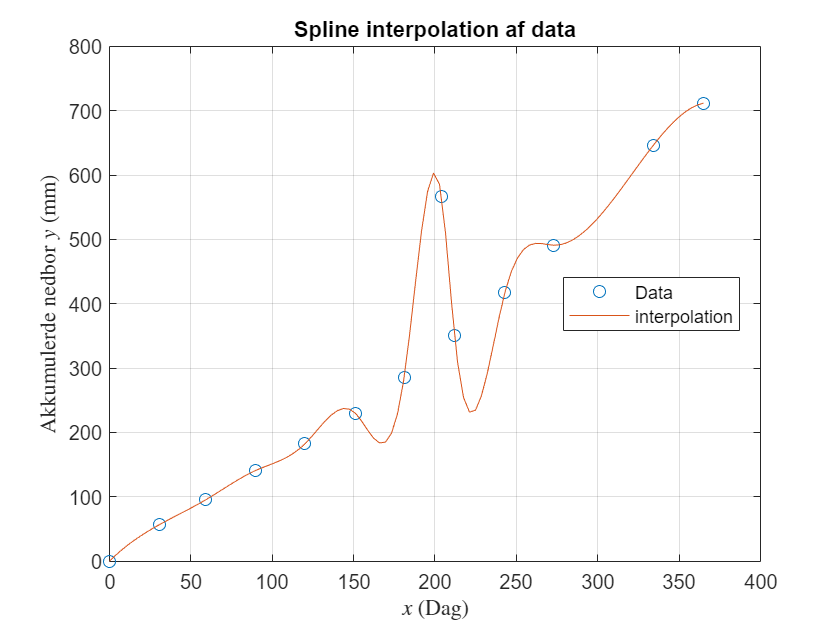

ned_spl_cub = spline(x,y,xx); % der laves igen en interpolation af dataen nu bruges linspacen fra
% tidliger til at danne 100 punkter som kurven kan følge


%der plottes
figure
plot(x,y,'o', 'DisplayName', 'Data') %data plottes
hold on
plot(xx,ned_spl_cub, 'DisplayName', 'interpolation') % interpolation plottes

% formalier
legend('location', 'best')
title('Spline interpolation af data')
xlabel('$x$ (Dag)', 'interpreter', 'latex')
ylabel('Akkumulerde nedbor $y$ (mm)', 'interpreter', 'latex')
grid
hold off

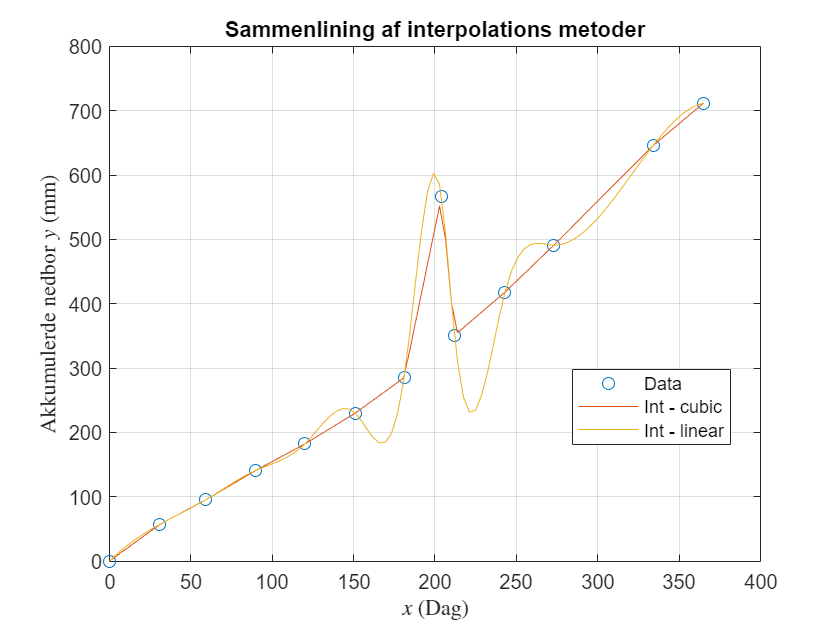

ned_int_lin = interp1(x,y,xx,"linear");
%der vises begge plot samlede for bedre forståelse
%der plottes
figure
plot(x,y,'o', 'DisplayName', 'Data') %data plottes
hold on
plot(xx,ned_int_lin, 'DisplayName', 'Int - cubic') % interpolation plottes
plot(xx,ned_spl_cub, 'DisplayName', 'Int - linear')

% formalier
legend('location', 'best')
title('Sammenlining af interpolations metoder')
xlabel('$x$ (Dag)', 'interpreter', 'latex')
ylabel('Akkumulerde nedbor $y$ (mm)', 'interpreter', 'latex')
grid
hold off

Det ser ud til at være den lineær interpolation der passer bedst i dette tilfælde.

Dette begrundes især med udsvingen i mellem punkt 6 og 7 samt 9 og 11.

# M3NUM1 E18 Ordinær eksamen opgave 3

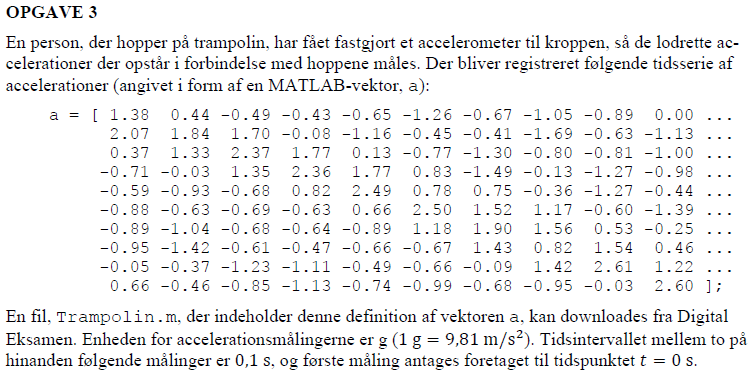

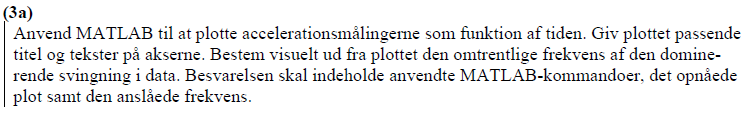

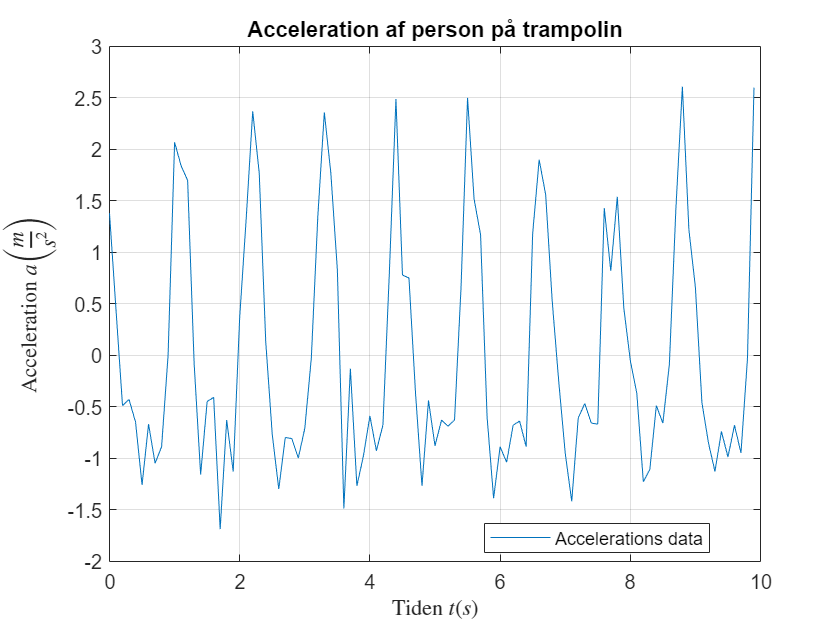

clear
a = [ 1.38 0.44 -0.49 -0.43 -0.65 -1.26 -0.67 -1.05 -0.89 0.00 ...
2.07 1.84 1.70 -0.08 -1.16 -0.45 -0.41 -1.69 -0.63 -1.13 ...
0.37 1.33 2.37 1.77 0.13 -0.77 -1.30 -0.80 -0.81 -1.00 ...
-0.71 -0.03 1.35 2.36 1.77 0.83 -1.49 -0.13 -1.27 -0.98 ...
-0.59 -0.93 -0.68 0.82 2.49 0.78 0.75 -0.36 -1.27 -0.44 ...
-0.88 -0.63 -0.69 -0.63 0.66 2.50 1.52 1.17 -0.60 -1.39 ...
-0.89 -1.04 -0.68 -0.64 -0.89 1.18 1.90 1.56 0.53 -0.25 ...
-0.95 -1.42 -0.61 -0.47 -0.66 -0.67 1.43 0.82 1.54 0.46 ...
-0.05 -0.37 -1.23 -1.11 -0.49 -0.66 -0.09 1.42 2.61 1.22 ...
0.66 -0.46 -0.85 -1.13 -0.74 -0.99 -0.68 -0.95 -0.03 2.60 ]; %data for accelerationen

t = 0:0.1:(length(a)/10-0.1); %der laves data for tiden
% her trækkes fra og divideres for at få den rigtige dimention.

figure
plot(t,a, 'DisplayName', 'Accelerations data') %data plottes

% formalier
legend('location', 'best')
title('Acceleration af person på trampolin')
xlabel('Tiden $t(s)$', 'interpreter', 'latex')
ylabel('Acceleration $a \left(\frac{m}{s^2}\right)$', 'interpreter', 'latex')
grid

Der tælles 9 toppe over 10 sekunder således for vi

$f = \frac{9}{10} Hz$ for den dominerende svining i plottet

y = fft(a)

y =   -4.0000e-02 + 0.0000e+00i  -3.0193e-01 - 3.1026e-01i  -1.7952e+00 + 1.1272e+00i  -2.3883e+00 + 1.3708e+00i  -2.0783e+00 - 2.0198e+00i  -2.6038e+00 - 2.5561e-01i   2.3706e+00 - 2.6115e+00i   8.9938e-01 - 2.0011e-01i   2.4786e+00 + 5.0526e+00i   6.7417e+01 + 1.0464e+01i  -3.3262e+00 - 9.0207e-01i  -2.8436e+00 - 1.9332e+00i  -2.1993e+00 + 2.7305e+00i  -2.6015e+00 - 2.1334e+00i   9.2963e-01 - 1.8996e+00i   1.7073e+00 - 1.6406e+00i   2.2321e+00 + 3.8120e+00i  -3.1181e+00 + 8.3531e+00i   2.9310e+01 + 8.2043e+00i  -1.6807e+00 + 1.1109e+00i   8.1077e-01 - 4.5055e-01i   1.4186e+00 + 1.6140e+00i  -1.5966e+00 - 1.5372e-01i  -4.8713e-01 + 1.5788e+00i  -6.5452e-01 + 2.7785e+00i   3.3000e+00 + 3.7600e+00i   3.7884e+00 + 5.4018e+00i   2.2791e+00 + 7.9913e+00i  -4.3376e+00 - 2.3077e+00i  -9.8225e-02 + 2.8793e+00i   1.9062e+00 + 1.6878e+00i  -2.0660e+00 + 1.5996e+00i   6.8721e+00 + 2.4906e+00i   3.1915e+00 - 1.0367e+00i  -2.7154e+00 + 4.0584e+00i  -7.4433e-01 - 3.6016e+00i  -7.4758e+00 + 2.1799e+


figure
plot(t,y, 'DisplayName', 'Accelerations data') %data plottes

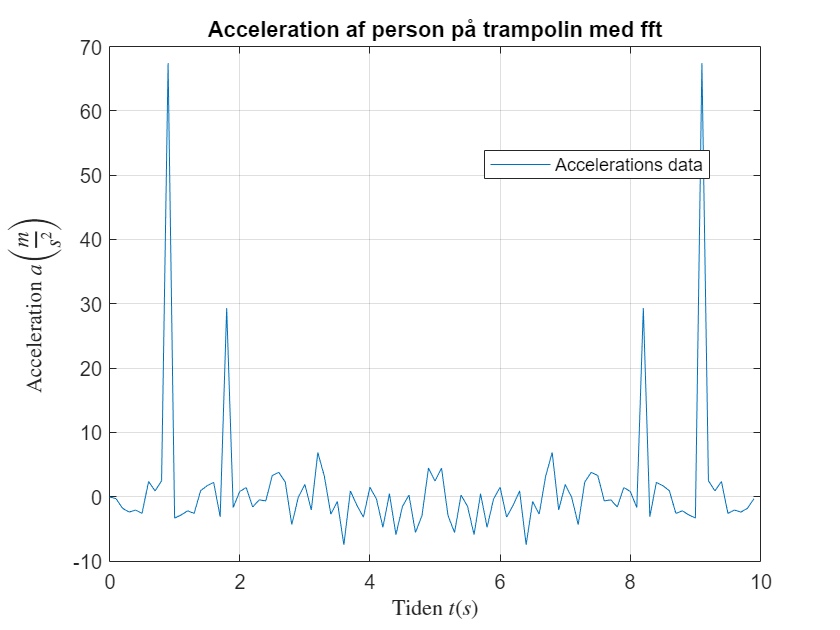


% formalier
legend('location', 'best')
title('Acceleration af person på trampolin med fft')
xlabel('Tiden $t(s)$', 'interpreter', 'latex')
ylabel('Acceleration $a \left(\frac{m}{s^2}\right)$', 'interpreter', 'latex')
grid


help fft

 fft Discrete Fourier transform.
    fft(X) is the discrete Fourier transform (DFT) of vector X.  For
    matrices, the fft operation is applied to each column. For N-D
    arrays, the fft operation operates on the first non-singleton
    dimension.
 
    fft(X,N) is the N-point fft, padded with zeros if X has less
    than N points and truncated if it has more.
 
    fft(X,[],DIM) or fft(X,N,DIM) applies the fft operation across the
    dimension DIM.
    
    For length N input vector x, the DFT is a length N vector X,
    with elements
                     N
       X(k) =       sum  x(n)*exp(-j*2*pi*(k-1)*(n-1)/N), 1 <= k <= N.
                    n=1
    The inverse DFT (computed by IFFT) is given by
                     N
       x(n) = (1/N) sum  X(k)*exp( j*2*pi*(k-1)*(n-1)/N), 1 <= n <= N.
                    k=1
 
    See also 